%{
    Calibration/Preprocessing:

    - This stage is there to mimic some form of calibration for a user,
    similar to how many voice assistants need a vocal sample to deal with.

    - This process takes multiple copies of the same word/phoneme and then
    creates an "average" of those waveforms, by doing this the level of
    variance the user can have on their voice when they are saying
    something to be speech recognized will be generally closer to the
    average.

    - To simplify the process for demonstration purposes we opted for 6
    takes per word/signal, but in the real usage case of machine learning
    there are upwards of millions of takes of different people saying
    specific words that can be averaged to find a signal profile for that word.

    Note: This mlx file does the same thing as preProcessor.m, but has visual
    and audio elements to better visualize the process while we were
    writing the code to "average" the sounds.

    WARNING: If the last section of code is run it will play a sound! Please
    be aware of this so as not be startled when it does.

%}

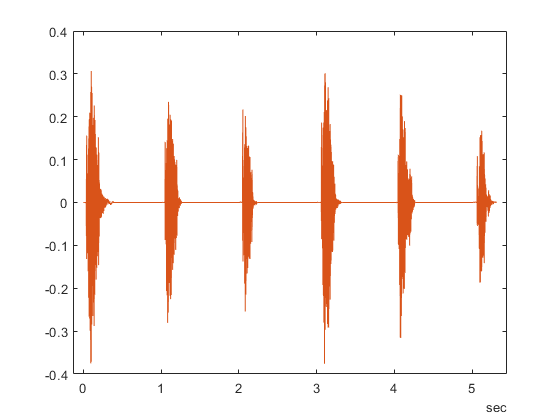

clf
fileName ="Phonemes\2.mp3";
plotAudio(fileName);

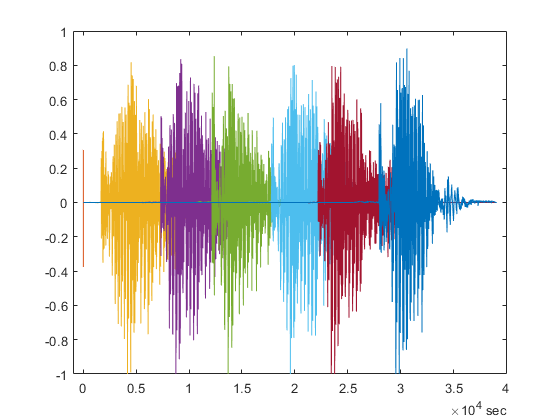

[y, fs] = audioread(fileName);
y = y(:,2);
duration = (length(y)-1)/fs;

clear("normalizedYs")

%{
    Splitting & Normalization:

    Takes the combined Audio Recording of 6 repetitions and cuts it up into
    single takes each. Then it normalizes those audios so that their
    volumes are equal as they are set to 1;
%}

hold on;
normalizedYs = {0, 0, 0, 0, 0, 0};
for i = 1:6
    normalizedYs{i} = normalizeAudio(y(floor(duration*((i-1)/6)*fs)+1:floor(duration*(i/6)*fs)));
    plot(normalizedYs{i});
end
hold off;

%{
    Moving Mean & Zero Padding:
    
    The algorithm uses a moving mean to find the point where the average of
    the signal goes past 0. The moving mean is used so that minor changes
    due to static or noise are not interfering with lining up the signals.

    The signals are then zero padded to the size of the longest signal out
    of the group of 6 signals. This is so that their fft can be computed
    then averaged.
%}
max = 0;
for i = 1:6
    idx = find(movmean(abs(normalizedYs{i}),[500,500])>(2*10^-3));
    id0 = idx(1);
    idend = idx(end);
    normalizedYs{i} = normalizedYs{i}(id0:idend);
    if(length(normalizedYs{i})>max)
        max = length(normalizedYs{i});
    end
end

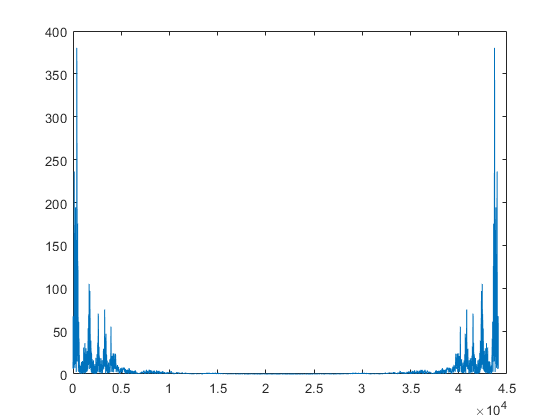

%{
    Average FFT:

    The way to find the average of multiple takes to create a profile of
    that sound that the user inputs is to take its frequencies and find the
    average. Therefore the FFT is computed for each of the 6 takes then
    averaged to find and magnify the frequencies that are most in common.
    This can then be Inverse Fourier Transformed into a signal that is now
    the average of all 6 takes that the user makes of the sound.
%}
avgfft = 0;
for i = 1:6
    normalizedYs{i} = [normalizedYs{i}; zeros(max-length(normalizedYs{i}),1)];
    avgfft = fft(normalizedYs{i},fs);
end
plot(abs(avgfft));

averageSound = ifft(avgfft);
length(averageSound);

ans = 44100

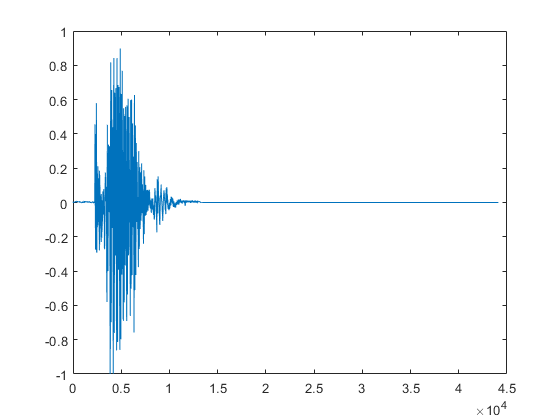

%{
    Final Result:

    After processing the signals and combining them
%}
plot(averageSound);

sound(averageSound,fs);